cd 'C:\Users\Mohammad Afaq\OneDrive\Documents\LUMS-Shared\ShareAbleSprojFolder\sproj research\Work\PPG signal Processing\RemovingMotionArtifacts\FrameWork'
data=xlsread("testing.xlsx");
[perf, PPG]=pre_process(butterworth,data(:,3),64);
ACC_data=(abs(data(:,7))+abs(data(:,8))+abs(data(:,9)))/3;
t1=5

t1 = 5

t2=9

t2 = 9

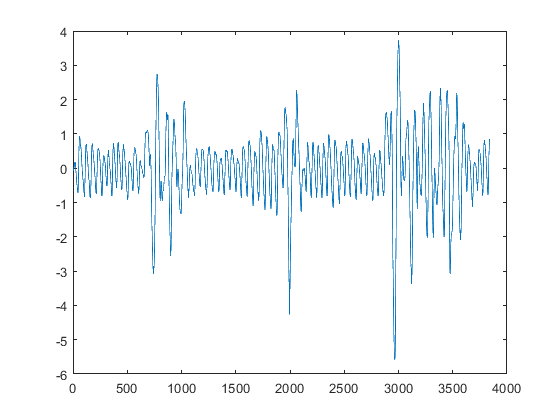

figure
plot(PPG)

%figure 
%freq_plot(PPG(t1*64:t2*64),64)


windows=[30 34]

windows =     30    34


data =    -0.6116
   -0.6724
   -0.7197
   -0.7671
   -0.8126
   -0.8232
   -0.7843
   -0.7040
   -0.5945
   -0.4593


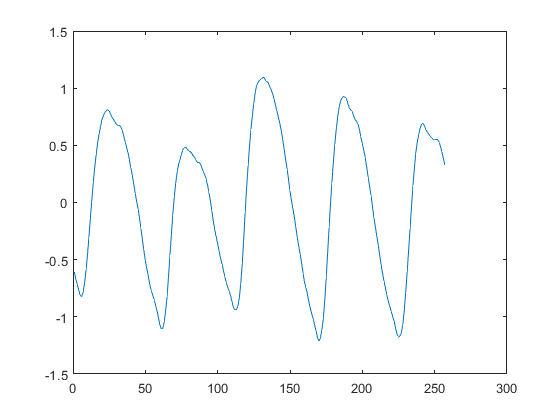

if (windows(1)-5)>0
    data=PPG((windows(1)-5)*64:(windows(1)-1)*64)
    plot(data)
else
    display("need more data to calibrate")
end


double_der=diff(diff(data));

[peaks,locs]=findpeaks(double_der,'MinPeakHeight',0.02,"MinPeakDistance",32);

distances=[];

for i=1:length(locs)-1
    distances=[distances abs(locs(i)-locs(i+1))];
end

len=min(distances);

PPG_sum=[];
for i=1:length(locs)-1
    PPG_sum=[PPG_sum data(locs(i):locs(i)+len)];
end


sum=zeros(len+1,1);
for i=1:length(distances)
    sum=sum+PPG_sum(:,i);
end


Averaged=sum/length(distances);
figure('Position', get(0, 'Screensize'))
t=1:1:length(Averaged)

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t=t/64

t =     0.0156    0.0313    0.0469    0.0625    0.0781    0.0938    0.1094    0.1250    0.1406    0.1563    0.1719    0.1875    0.2031    0.2188    0.2344    0.2500    0.2656    0.2813    0.2969    0.3125    0.3281    0.3438    0.3594    0.3750    0.3906    0.4063    0.4219    0.4375    0.4531    0.4688    0.4844    0.5000    0.5156    0.5313    0.5469    0.5625    0.5781    0.5938    0.6094    0.6250    0.6406    0.6563    0.6719    0.6875    0.7031    0.7188    0.7344    0.7500    0.7656    0.7813


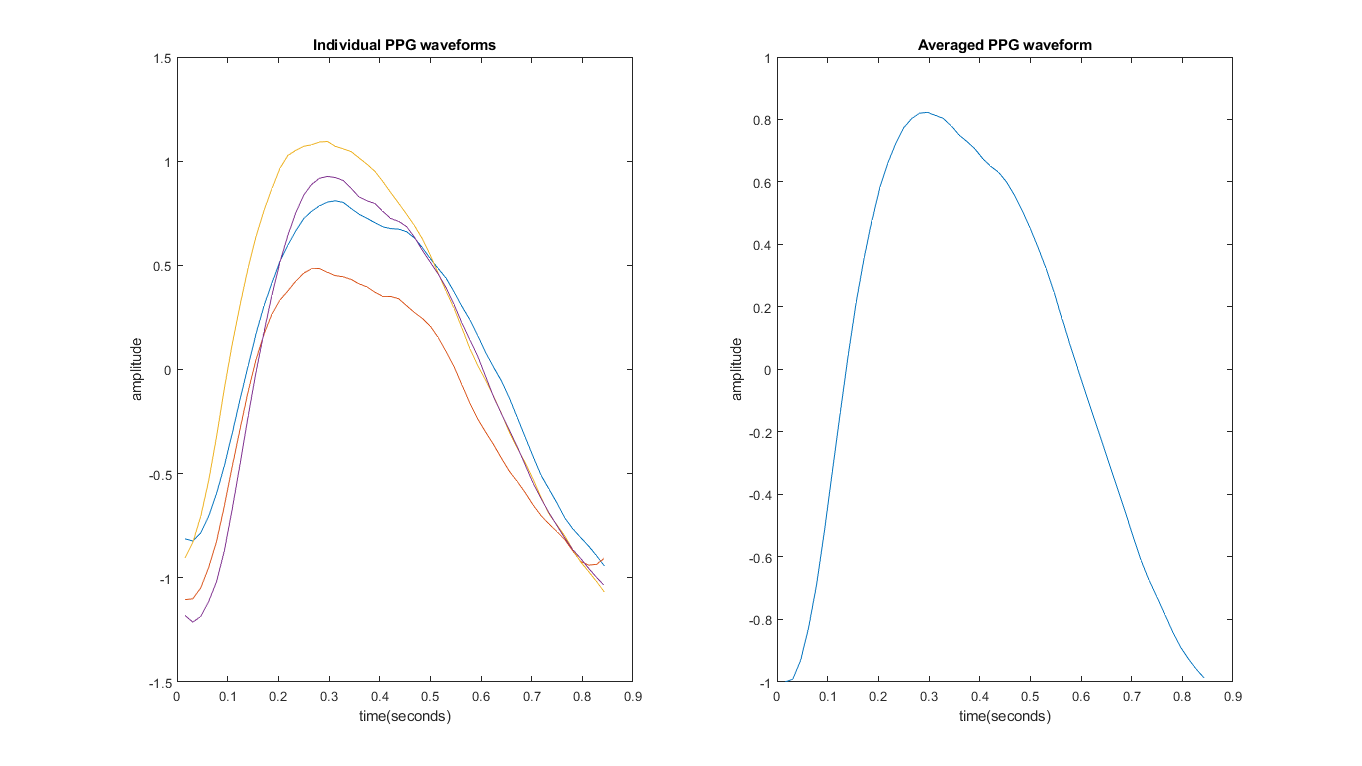

subplot(1,2,1)
plot(t,PPG_sum)
xlabel('time(seconds)')
ylabel('amplitude')
title('Individual PPG waveforms')
subplot(1,2,2)
plot(t,Averaged)
xlabel('time(seconds)')
ylabel('amplitude')
title('Averaged PPG waveform')

window=windows(2)-windows(1);
samples=window*64;
d=length(Averaged);
bias=Averaged(length(Averaged))-Averaged(1);



second_sample=PPG(windows(1)*64+1)

second_sample = 0.1288

first_sample=PPG(windows(1)*64)

first_sample = 0.1918

last_sample=PPG((windows(1)*64)-1)

last_sample = 0.2573


if second_sample>first_sample 
    if first_sample>last_sample
        grad='positive'
    end
end

if second_sample<first_sample 
    if first_sample<last_sample
        grad='negative'
    end
end

grad = 'negative'


if grad=='negative'
    for i=2:length(Averaged)-1
        gradi=Averaged(i+1)-Averaged(i-1);
        if gradi<0
            if Averaged(i)>second_sample && Averaged(i)<first_sample
                initial_index=i
            end
        end
    end
elseif grad=='positive'
    for i=2:length(Averaged)-1
        gradi=Averaged(i+1)-Averaged(i-1);
        if gradi>0
            if Averaged(i)<second_sample && Averaged(i)>first_sample
                initial_index=i
            end
        end
    end
end

initial_index = 36


replace=[Averaged(initial_index:length(Averaged))];


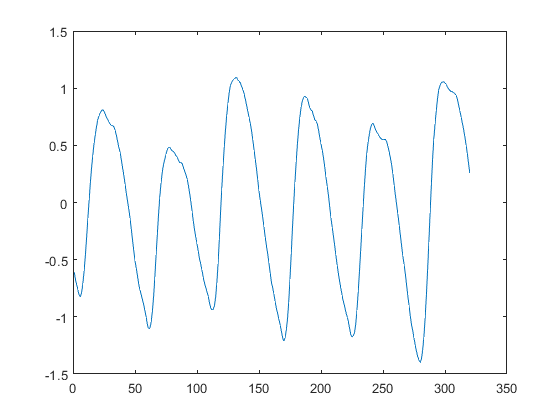



used=length(Averaged)-initial_index;
figure
plot(PPG(((windows(1)-5)*64):(windows(1)*64)-1))


choice=[];
i=1;
while(used<samples)
    if (samples-used)<d
        choice=Averaged(1:samples-used)
    else
        choice=Averaged
    end
    choice=choice+i*bias
    replace=[replace;choice]
    used=used+length(choice)
    i=i+1
end

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9892
   -0.9799
   -0.9189
   -0.8139
   -0.6779
   -0.5046
   -0.3140
   -0.1257
    0.0576
    0.2255


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 72

i = 2

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9776
   -0.9683
   -0.9073
   -0.8023
   -0.6663
   -0.4930
   -0.3024
   -0.1141
    0.0692
    0.2371


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 126

i = 3

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9660
   -0.9567
   -0.8957
   -0.7907
   -0.6547
   -0.4814
   -0.2908
   -0.1025
    0.0808
    0.2487


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 180

i = 4

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9544
   -0.9451
   -0.8841
   -0.7791
   -0.6431
   -0.4698
   -0.2792
   -0.0909
    0.0924
    0.2603


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 234

i = 5

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9428
   -0.9335
   -0.8725
   -0.7675
   -0.6315
   -0.4582
   -0.2676
   -0.0793
    0.1040
    0.2719


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 256

i = 6

trend=sgolayfilt(replace,1,1*64+1)

trend =    -0.4152
   -0.4026
   -0.3900
   -0.3774
   -0.3648
   -0.3522
   -0.3397
   -0.3271
   -0.3145
   -0.3019


temp=replace-trend

temp =     0.5775
    0.4822
    0.3911
    0.3004
    0.2119
    0.1249
    0.0340
   -0.0533
   -0.1420
   -0.2345



figure('Position', get(0, 'Screensize'))

shift=temp(1)-last_sample

shift = 0.3202

temp=temp-shift

temp =     0.2573
    0.1620
    0.0709
   -0.0198
   -0.1083
   -0.1953
   -0.2862
   -0.3735
   -0.4622
   -0.5547


t=1:1:length(temp)

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t=t/64

t =     0.0156    0.0313    0.0469    0.0625    0.0781    0.0938    0.1094    0.1250    0.1406    0.1563    0.1719    0.1875    0.2031    0.2188    0.2344    0.2500    0.2656    0.2813    0.2969    0.3125    0.3281    0.3438    0.3594    0.3750    0.3906    0.4063    0.4219    0.4375    0.4531    0.4688    0.4844    0.5000    0.5156    0.5313    0.5469    0.5625    0.5781    0.5938    0.6094    0.6250    0.6406    0.6563    0.6719    0.6875    0.7031    0.7188    0.7344    0.7500    0.7656    0.7813


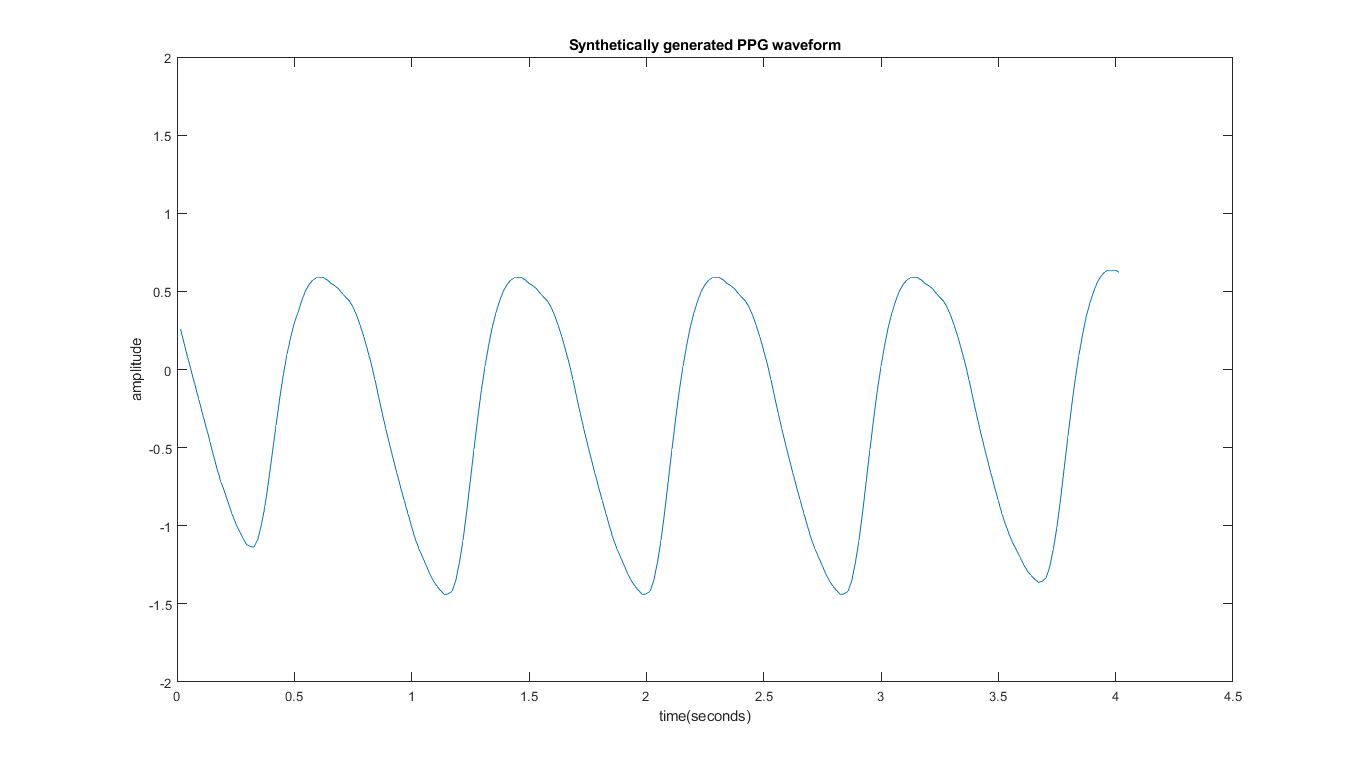

plot(t,temp)
xlabel('time(seconds)')
ylabel('amplitude')
title('Synthetically generated PPG waveform')
ylim([-2 2])

data =    -0.6116
   -0.6724
   -0.7197
   -0.7671
   -0.8126
   -0.8232
   -0.7843
   -0.7040
   -0.5945
   -0.4593


second_sample = 0.1288

first_sample = 0.1918

last_sample = 0.2573


grad =

  0×0 empty char array



initial_index = 0

initial_index = 36

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9892
   -0.9799
   -0.9189
   -0.8139
   -0.6779
   -0.5046
   -0.3140
   -0.1257
    0.0576
    0.2255


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 72

i = 2

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9776
   -0.9683
   -0.9073
   -0.8023
   -0.6663
   -0.4930
   -0.3024
   -0.1141
    0.0692
    0.2371


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 126

i = 3

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9660
   -0.9567
   -0.8957
   -0.7907
   -0.6547
   -0.4814
   -0.2908
   -0.1025
    0.0808
    0.2487


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 180

i = 4

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9544
   -0.9451
   -0.8841
   -0.7791
   -0.6431
   -0.4698
   -0.2792
   -0.0909
    0.0924
    0.2603


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 234

i = 5

choice =    -1.0008
   -0.9915
   -0.9305
   -0.8255
   -0.6895
   -0.5162
   -0.3256
   -0.1373
    0.0460
    0.2139


choice =    -0.9428
   -0.9335
   -0.8725
   -0.7675
   -0.6315
   -0.4582
   -0.2676
   -0.0793
    0.1040
    0.2719


replace =     0.1623
    0.0796
    0.0011
   -0.0770
   -0.1530
   -0.2273
   -0.3057
   -0.3804
   -0.4565
   -0.5364


used = 256

i = 6

trend =    -0.4152
   -0.4026
   -0.3900
   -0.3774
   -0.3648
   -0.3522
   -0.3397
   -0.3271
   -0.3145
   -0.3019


replace =     0.5775
    0.4822
    0.3911
    0.3004
    0.2119
    0.1249
    0.0340
   -0.0533
   -0.1420
   -0.2345


PPG =    -0.0221
   -0.0608
   -0.0630
   -0.0420
   -0.0268
   -0.0321
   -0.0350
   -0.0093
    0.0101
    0.0240


PPG(windows(1)*64:windows(2)*64)=Averaging_window(PPG,[30 34])

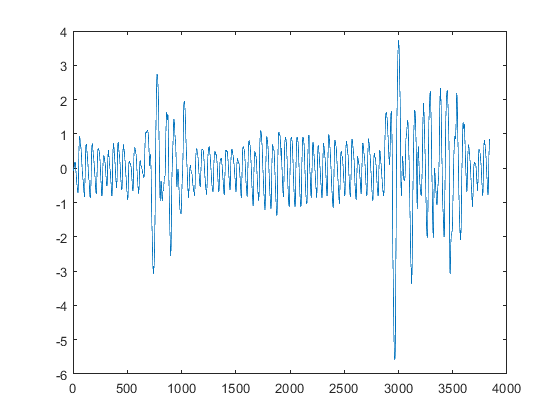

plot(PPG)

function [replace] = Averaging_window(PPG,windows)

    if (windows(1)-5)>0
        data=PPG((windows(1)-5)*64:(windows(1)-1)*64)
        plot(data)
    else
        display("need more data to calibrate")
        return
    end
    
    double_der=diff(diff(data));

    [peaks,locs]=findpeaks(double_der,'MinPeakHeight',0.02,"MinPeakDistance",32);
    
    distances=[];
    
    for i=1:length(locs)-1
        distances=[distances abs(locs(i)-locs(i+1))];
    end
    
    len=min(distances);
    
    PPG_sum=[];
    for i=1:length(locs)-1
        PPG_sum=[PPG_sum data(locs(i):locs(i)+len)];
    end
    
    sum=zeros(len+1,1);
    for i=1:length(distances)
        sum=sum+PPG_sum(:,i);
    end
    
    Averaged=sum/length(distances);
    %plot(PPG_sum)
    %plot(Averaged)
    
    
    window=windows(2)-windows(1);
    samples=window*64;
    d=length(Averaged);
    bias=Averaged(length(Averaged))-Averaged(1);
    
    
    second_sample=PPG(windows(1)*64+1)
    first_sample=PPG(windows(1)*64)
    last_sample=PPG((windows(1)*64)-1)
    grad=''
    initial_index=0
    if second_sample>first_sample 
        if first_sample>last_sample
            %grad='positive'
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi>0
                    if Averaged(i)<second_sample && Averaged(i)>first_sample
                        initial_index=i
                    end
                end
            end
        end
    end
    
    if second_sample<first_sample 
        if first_sample<last_sample
            %grad='negative'
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi<0
                    if Averaged(i)>second_sample && Averaged(i)<first_sample
                        initial_index=i
                    end
                end
            end
        end
    end

    
    replace=[Averaged(initial_index:length(Averaged))];
    used=length(Averaged)-initial_index;
    %plot(replace)
    
    choice=[];
    i=1;
    while(used<samples)
        if (samples-used)<d
            choice=Averaged(1:samples-used)
        else
            choice=Averaged
        end
        choice=choice+i*bias
        replace=[replace;choice]
        used=used+length(choice)
        i=i+1
    end
    
    trend=sgolayfilt(replace,1,1*64+1)
    %plot(replace)
    figure
    %plot(replace-trend)
    replace=replace-trend
    %plot(PPG)
end

function Hd = stopbandfilter(freq)
    %STOPBANDFILTER Returns a discrete-time filter object.
    
    % MATLAB Code
    % Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
    % Generated on: 06-Apr-2021 11:59:52
    
    % FIR Window Bandstop filter designed using the FIR1 function.
    
    % All frequency values are in Hz.
    Fs = 64;  % Sampling Frequency
    
    N    = 10;      % Order
    Fc1  = freq-freq/4;      % First Cutoff Frequency
    Fc2  = freq+freq/4;        % Second Cutoff Frequency
    flag = 'scale';  % Sampling Flag
    Beta = 0.5;      % Window Parameter
    
    % Create the window vector for the design algorithm.
    win = kaiser(N+1, Beta);
    
    % Calculate the coefficients using the FIR1 function.
    b  = fir1(N, [Fc1 Fc2]/(Fs/2), 'stop', win, flag);
    Hd = dfilt.dffir(b);
end

function [perf, PPG] = pre_process(fil,data,fs)
    perf=sgolayfilt(data,2,4*fs +1);
    PPG=data-perf;
    PPG=-1*PPG;
    PPG=filter(fil,PPG);
    PPG=normalize(PPG);
    
end
function [FF,FM]=freq_plot(data,fs)
    FM = (abs(fftshift(fft(data)))); 	
    FF = linspace(-fs/2,fs/2,length(FM)); 
    plot(FF,FM)
    xlim([0.05 10])
end
function Hd = butterworth
    %BUTTERWORTH Returns a discrete-time filter object.
    
    % MATLAB Code
    % Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
    % Generated on: 02-Apr-2021 15:37:40
    
    % Butterworth Bandpass filter designed using FDESIGN.BANDPASS.
    
    % All frequency values are in Hz.
    Fs = 64;  % Sampling Frequency
    
    N   = 2;    % Order
    Fc1 = 0.6;  % First Cutoff Frequency
    Fc2 = 4;    % Second Cutoff Frequency
    
    % Construct an FDESIGN object and call its BUTTER method.
    h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
    Hd = design(h, 'butter');
end